load("4signs_trainingdata_29.mat")

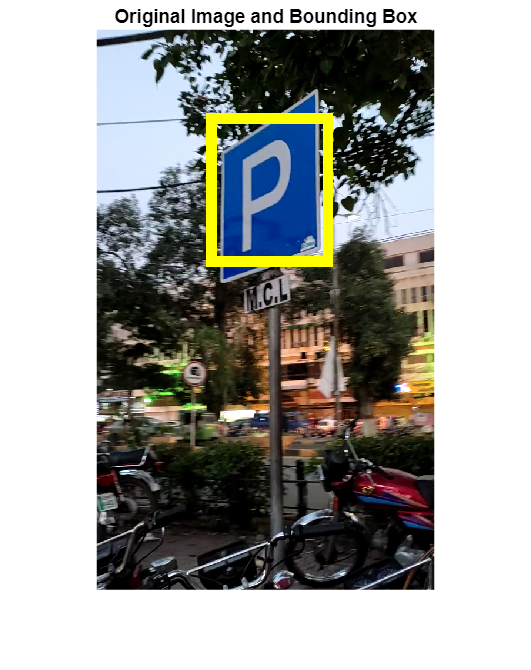

n = 16;
filenameImage = trainingData.imageFilename{n};
I = imread(filenameImage);
bbox = [trainingData.TrafficSign{n}];
label = "TrafficSign";
% display the image and bounding box.

annotatedImage = insertShape(I,"rectangle",bbox,"LineWidth",18);
imshow(annotatedImage)
title('Original Image and Bounding Box')

**Resize Image **

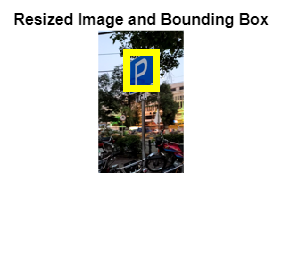

scale = 1/6;
J = imresize(I,scale);
bboxResized = bboxresize(bbox,scale);
annotatedImage = insertShape(J,"rectangle",bboxResized,"LineWidth",8);
imshow(annotatedImage)
title('Resized Image and Bounding Box')

**Random Rotation**

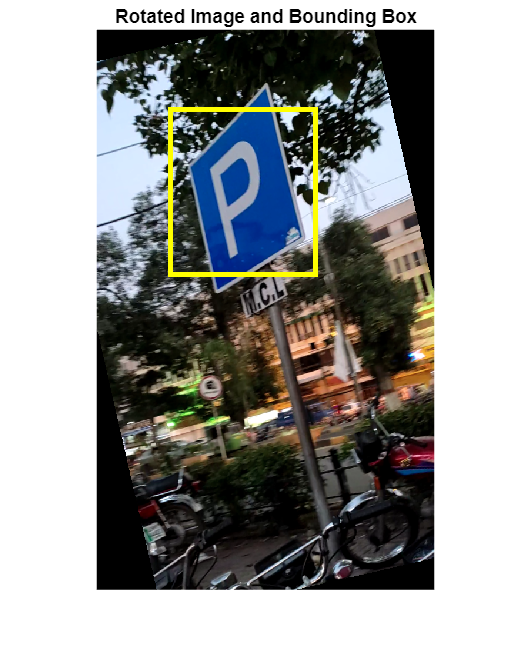

tform = randomAffine2d("Rotation",[-15 15]);
rout = affineOutputView(size(I),tform);
J = imwarp(I,tform,"OutputView",rout);
bboxRotated = bboxwarp(bbox,tform,rout,"OverlapThreshold",0.5);
annotatedImage = insertShape(J,"rectangle",bboxRotated,"LineWidth",8);
imshow(annotatedImage)
title('Rotated Image and Bounding Box')

**Random Scale**

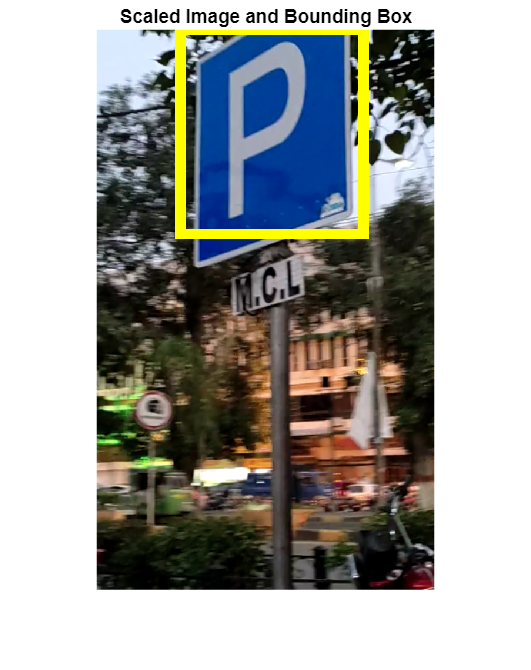

tform = randomAffine2d("Scale",[1.5 1.8]);
rout = affineOutputView(size(I),tform);
J = imwarp(I,tform,"OutputView",rout);
bboxScaled = bboxwarp(bbox,tform,rout,"OverlapThreshold",0.1);
annotatedImage = insertShape(J,"rectangle",bboxScaled,"LineWidth",18);
imshow(annotatedImage)
title('Scaled Image and Bounding Box')